# 'surface' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Environment

pl.include_begin('environment');
    pl.raw(['sky_sphere{ pigment{ gradient <0,0,1> '...
                      'color_map{ [0   color rgb<0.0,0.0, 0.0> ] '...
                                 '[0.4 color rgb<0.01, 0.01, 0.01>   ] '...
                                 '[0.9 color rgb<0.04, 0.04, 0.04>   ]  '...
                                 '[1.0 color rgb<0.1,  0.1,  0.1>    ]} '...
                      'scale 1  }}']);
pl.include_end();


#### Scene 1

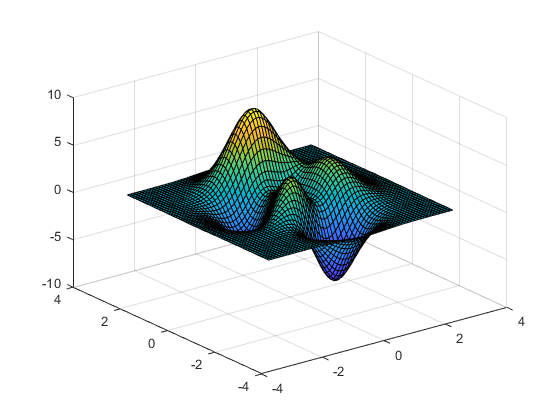

pl.scene_begin('scene_file', 'surface1.pov', 'image_file', 'surface1.png');
    pl.include("glass");
    pl.include("metals");
    pl.include("environment");    
       
    % Camera
    pl.camera('angle', 35, 'location', [-10 -10 6], 'look_at', [0 0 0], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2 2 2], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
    
    % Hide preview
    %f = figure('Visible', 'off');
    %ax = axes(f);

    % Surface
    size = 60;
    [X,Y,Z] = peaks(size);
    s = surf(X,Y,Z);

    % With checkerd texture
    pl.surface('surface', s, 'scale', [1, 1, 0.35], 'texture_odd', 'Gold_Nugget', 'texture_even', 'T_Ruby_Glass');

    % With color map
    % pl.surface('surface', s, 'colormap', 'jet', 'scale', [1, 1, 0.35], 'finish', 'ambient 0.1 diffuse 0.4 reflection 0.15 specular 5.4 roughness 0.4');
pl.scene_end();


#### Render and display

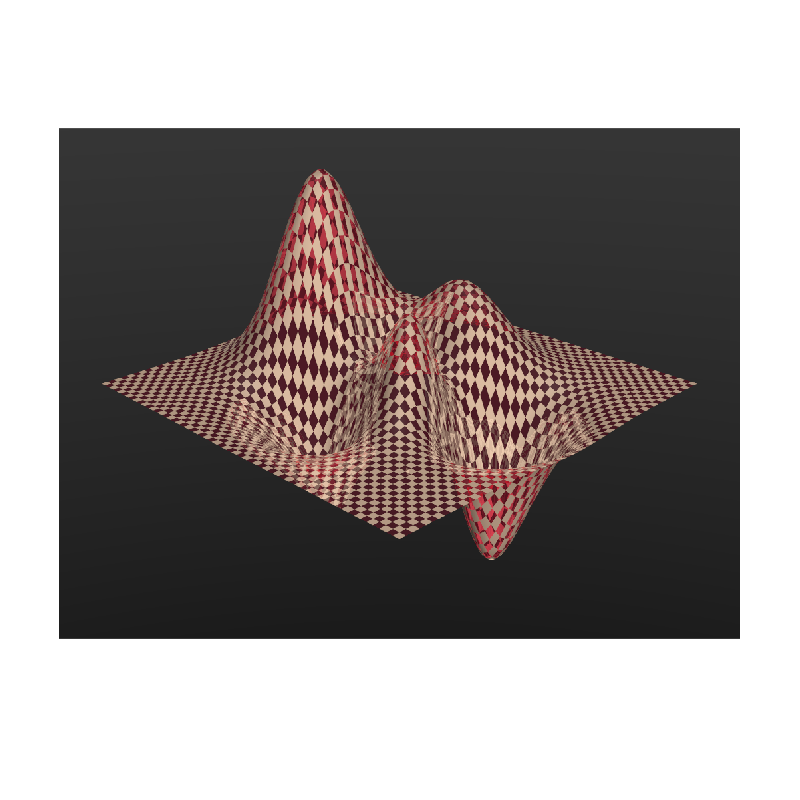

figure()
image = pl.render();
imshow(image);

#### Scene 2

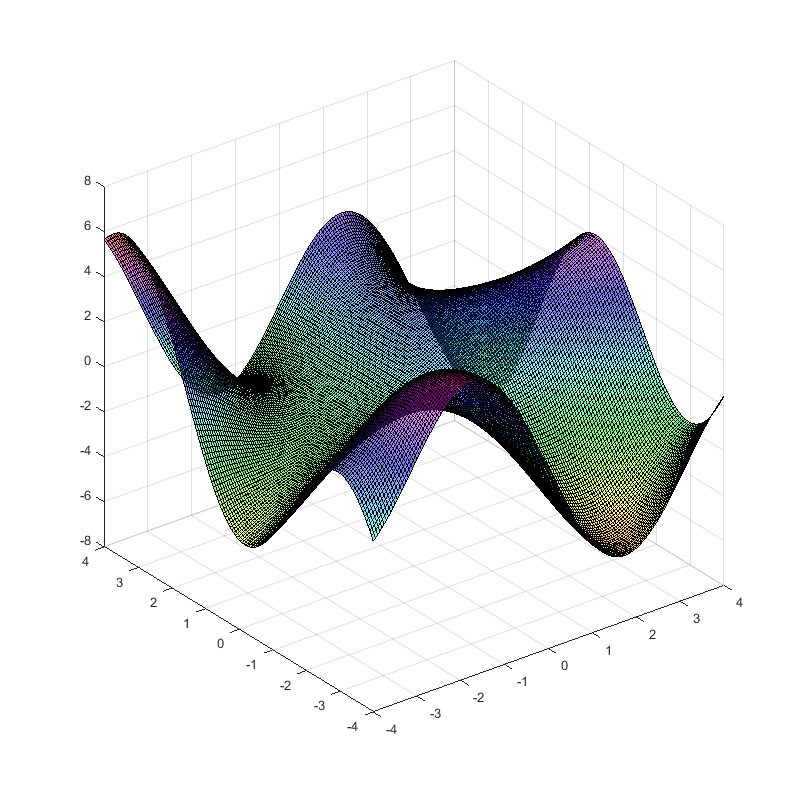

pl.scene_begin('scene_file', 'surface2.pov', 'image_file', 'surface2.png');
    pl.include("glass");
    pl.include("metals");
    pl.include("environment");    

    % Camera
    pl.camera('angle', 35, 'location', [-13 -13 8], 'look_at', [0 0.2 0], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2.5 2.5 2.5], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1],       'shadowless', true);

    % Hide preview
    % f = figure('Visible', 'off');
    % ax = axes(f);

    % Surface
    [X,Y] = meshgrid(-4:.2:4);
    Z = Y.*sin(X) + X.*cos(Y);
    s = surf(X,Y,Z,'FaceAlpha',0.5);

    % With checkerd texture
    % pl.surface('surface', s, 'scale', [1, 1, 0.35], 'texture_odd', 'Bright_Bronze', 'texture_even', 'Orange_Glass');

    % With color map
    pl.surface('surface', s, 'colormap', 'hsv', 'scale', [1, 1, 0.35], 'finish', 'ambient 0.01 diffuse 0.3 reflection 0.1 specular 5.4 roughness 0.4');

pl.scene_end();

#### Render and display

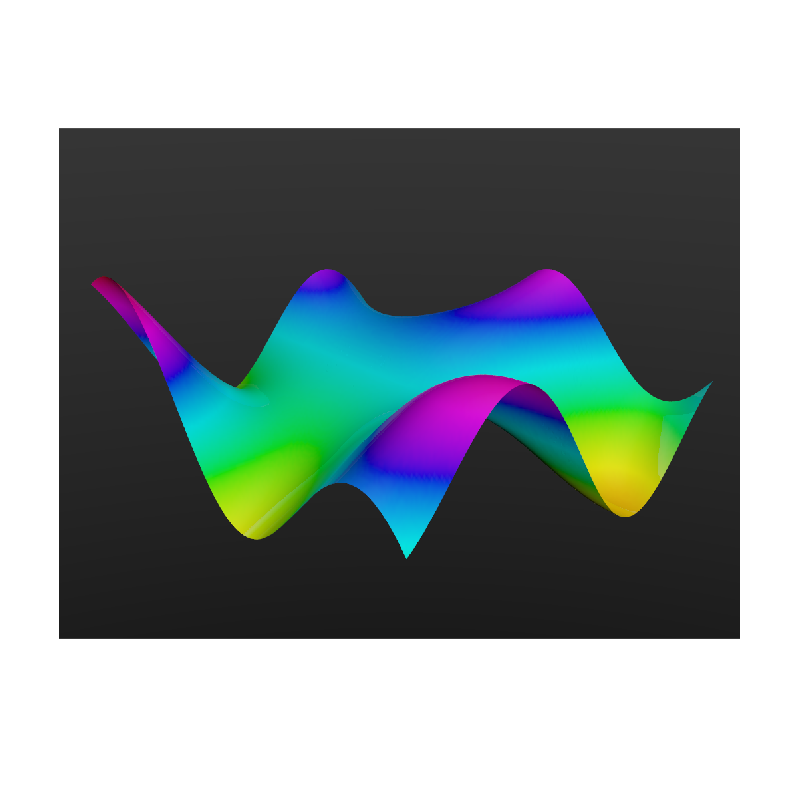

figure();
image = pl.render();
imshow(image);

#### Scene 3

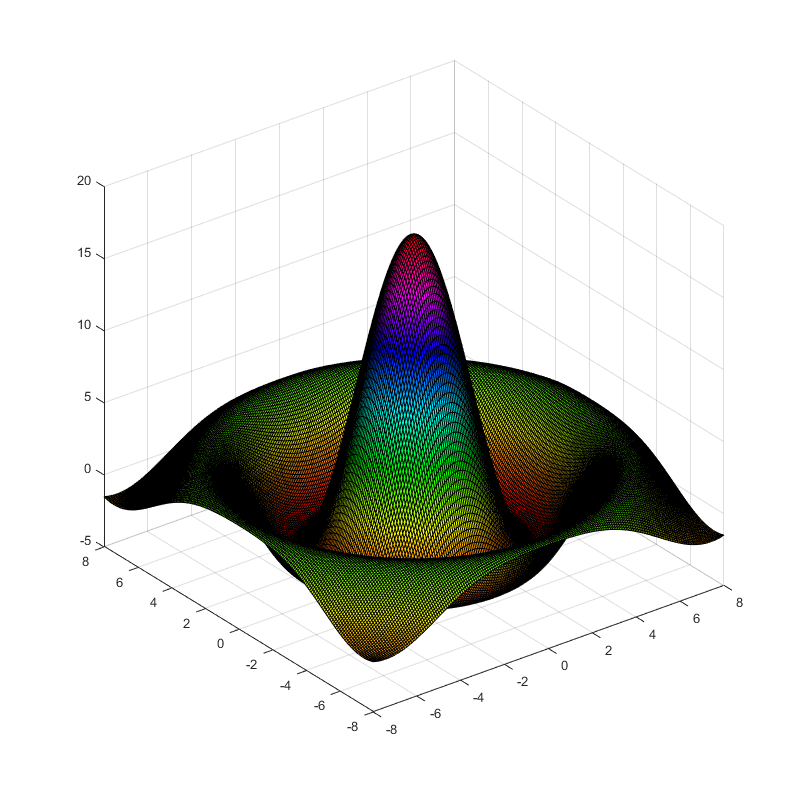

pl.scene_begin('scene_file', 'surface3.pov', 'image_file', 'surface3.png');
    pl.include("glass");
    pl.include("metals");
    pl.include("environment");    

    % Camera
    pl.camera('angle', 35, 'location', [-25 -25 14], 'look_at', [0 0 0.5], 'type', 'perspective');

    % Lights
    pl.light('location', [-10 -17 7],   'color', [2.5 2.5 2.5], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1],       'shadowless', true);

    % Hide preview
    %f = figure('Visible', 'off');
    %ax = axes(f);
    
    % Surface
    t = linspace (-8, 8, 50);
    [x, y] = meshgrid (t, t);
    r = sqrt (x .^ 2 + y .^ 2) + eps;
    z = 18 * sin (r) ./ r;
    s = surf(x,y,z);

    % With checkerd texture
    % pl.surface('surface', s, 'scale', [1, 1, 3/10], 'texture_odd', 'Aluminum', 'texture_even', 'T_Winebottle_Glass');
    
    % With color map
    finish = pl.declare("f", "finish {ambient 0.01 diffuse 0.3 reflection 0.1 specular 5.4 roughness 0.4}");
    pl.surface('surface', s, 'colormap', 'hsv', 'scale', [1, 1, 0.35], 'finish', finish);

pl.scene_end();

#### Render and display

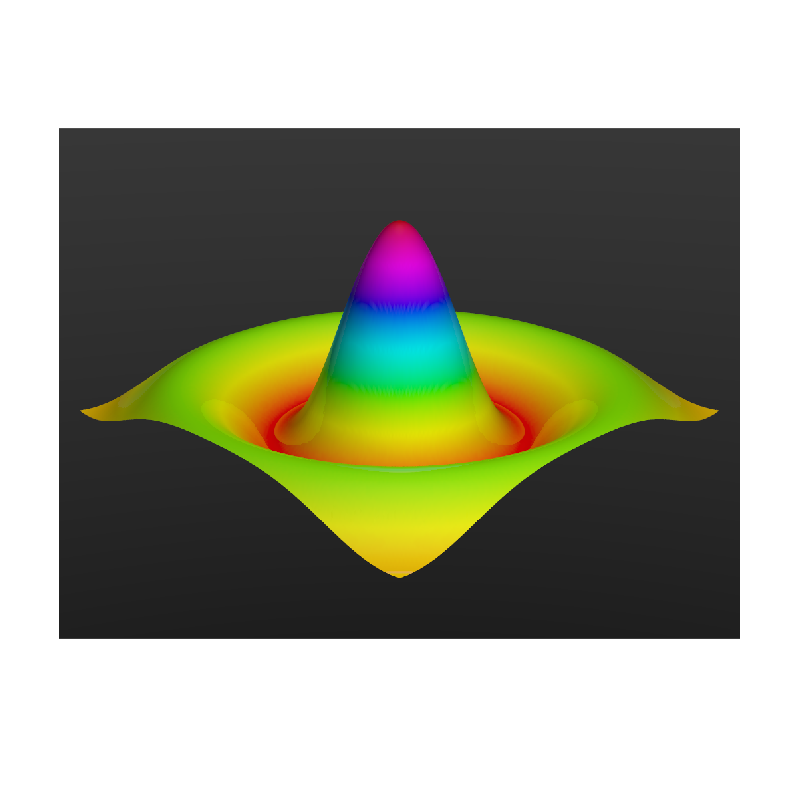

figure();
image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 1510.411281 seconds.
